# Trabalho final de ECM307 - Análise de vogais

## Boas Práticas

clear;      % limpa as variáveis
close all;  % fecha as janelas
clc;        %limpa a tela

## Lendo os Arquivos

% audioread Read audio files
%     [Y, FS] = audioread(FILENAME) reads an audio file specified by the
%     character vector or string scalar FILENAME, returning the sampled data
%     in Y and the sample rate FS, in Hertz.

%Lendo a vogal a

[Vg_a, fs_a] = audioread("2 - Fourier_Vogais_a.wav");

%%% Ouvir a vogal

sound(Vg_a,fs_a);

%%% Janelamento da vogal a

## Extraindo características no tempo

Na = length(Vg_a);      % número de pontos da vogal /a/
T = inv(fs_a);          % período de amostragem
Ta = (Na-1)*T;          % duração da vogal a
Picoa = max(abs(Vg_a)); % pico da vogal /a/
tempa = linspace(0,Ta,Na); % calibrando vetor tempo

## Visualizando as vogais

%%% Janelamento da vogal a
%hamming Hamming Window.

Jh_a = hamming(Na)

Jh_a =     0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800
    0.0800



%%% Vogal ponderada
Vg_ap = Jh_a.*Vg_a

Vg_ap =     0.0004
    0.0002
   -0.0001
   -0.0002
   -0.0001
   -0.0002
   -0.0003
   -0.0003
   -0.0001
    0.0002


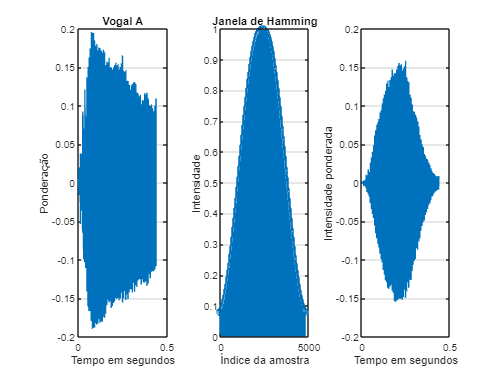


figure()

subplot(1,3,1)
plot(tempa, Vg_a);
xlabel('Tempo em segundos');
ylabel('Ponderação');
title('Vogal A')
grid();

subplot(1,3,2)
stem(Jh_a);
xlabel('Índice da amostra');
ylabel('Intensidade');
title('Janela de Hamming')
grid();

subplot(1,3,3)
plot(tempa, Vg_ap)
xlabel('Tempo em segundos');
ylabel('Intensidade ponderada');
grid();

## Análise de Fourier

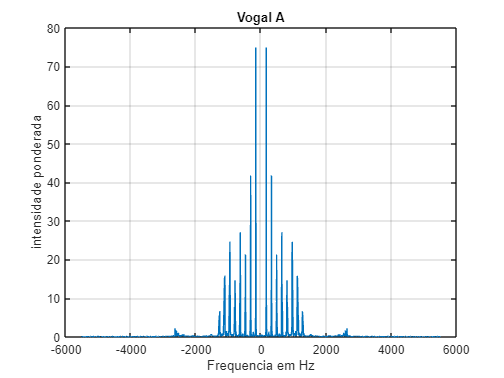

%%% Admitindo o sinal quase periódico 

Fourier_a = fft(Vg_ap);

%%% Calibrando o eixo frequencia

frequencia_a = linspace(-fs_a/2,fs_a/2,Na);

%%% Visualizando a tranformada rapida dde fourier

figure()

plot(frequencia_a, fftshift(abs(Fourier_a)));
xlabel('Frequencia em Hz');
ylabel('intensidade ponderada');
title('Vogal A')
grid();

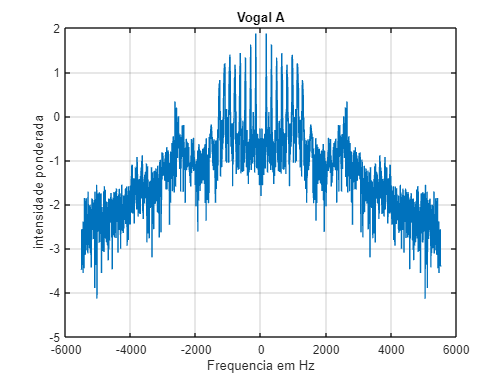

%%% Visualizano em escala log
figure()

plot(frequencia_a, fftshift(log10(abs(Fourier_a))));
xlabel('Frequencia em Hz');
ylabel('intensidade ponderada');
title('Vogal A')
grid();

## Extraindo características em frequência